# Lab B: Solving Systems of Linear Equations Describing Electrical Circuits

## Exercise 1

**Building equations for a simple circuit**

Recall from the prelab:

        Kirchoff's Voltage Law - The sum of voltages within a loop must equal zero.

        Kirchoff's Current Law - The sum of currents at a mode must equal zero.

        Ohm's Law -  For a resistor$V = IR$ where $V$ is the change in voltage, and $I$ is the current.

For the following circuit, we therefore have:

-     Two equations describing the two loops, and

-     Two equations describing the two nodes

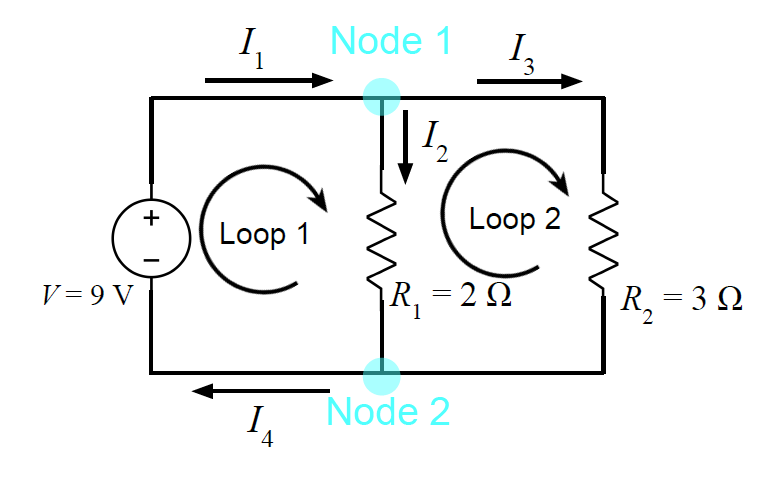

**The four equations are therefore:**

*        Node 1:* $I_1 - I_2 - I_3 = 0$

*        Node 2:* $I_2 + I_3 - I_4 = 0$

*        Loop 1:* $\Delta V_{\textrm{R1}} -V=I_2 R_1 -V=0$

*        Loop 2:* $-\Delta V_{\textrm{R1}} +\Delta V_{\textrm{R2}} =-I_2 R_1 +I_3 R_2 =0$

Note: the term $I_2 R_1$ in *Loop 2* also has a negative sign in front of it. This is because the direction of the voltage drop (downward, according to the current direction of $I_2$) is in the opposite of the direction of the loop (clockwise). This is just another sign convention you need to be careful of.

**Now we have 4 equations and 4 unknowns. There is a solution!**

### Solving the circuit using MATLAB...

Here, we pre-define some known variables to make the next step easier:

R1 = 2;
R2 = 3;
V = 9;

**Convert the system of four equations above into matrix form (**$A\;x=b$**) that we'll use to solve for **$I_1$**, **$I_2$**, **$I_3$**, and **$I_4$:

% Complete the code below:
A = [1 -1 -1 0; 0 1 1 -1; 0 2 0 0; 0 -2 3 0];
b = [0; 0; 9; 0];

**Solve the system of equations using the **`rref`** command:**

% Type in the solution below
rref([A [b]])

ans =     1.0000         0         0         0    7.5000
         0    1.0000         0         0    4.5000
         0         0    1.0000         0    3.0000
         0         0         0    1.0000    7.5000


**Solve the system of equations using the **`linsolve`** command:**

% Type in the solution below 
linsolve(A, b)

ans =     7.5000
    4.5000
    3.0000
    7.5000


**Solve the system of equations using the backslash operator:**

% Type in the solution below 
A\b

ans =     7.5000
    4.5000
    3.0000
    7.5000


## Exercise 2

Establish the system of equations for the following "bridge" circuit and solve for $I_1$, $I_2$, and $I_3$.

- Establish the system of equations based on the *presumptive* directions of the current flows given in the graph, and write out the system of equations.   

- Hint: for this question, you only need to use Kirchhoffs Voltage Law to establish a system of three questions since the unknown variables have already been reduced to just $I_1$, $I_2$, and $I_3$ by Kirchhoffs Current Law!

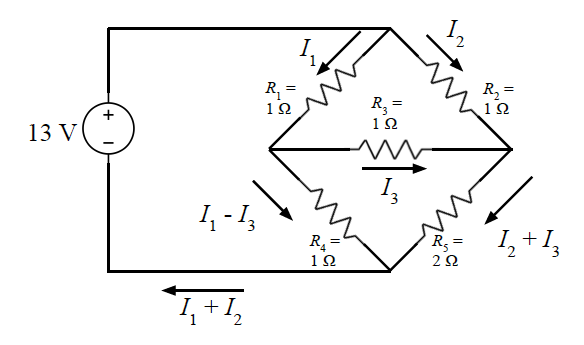

**Write out the system of equations below:**

$\Delta V_{\textrm{R1}} +\Delta V_{\textrm{R4}} -V=I_1 R_1 +\left(I_1 {-I}_3 \right)R_4 -V=I_1 \left(R_1 +R_4 \right)-I_3 R_4 -V=0$→ $I_1 \left(R_1 +R_4 \right)-I_3 R_4 =V$

 $\Delta V_{\textrm{R1}} +\Delta V_{\textrm{R3}} +\Delta V_{\textrm{R5}} -V=I_1 R_1 +I_3 R_3 +\left(I_2 {+I}_3 \right)R_5 -V=I_1 R_1 +I_2 R_5 +I_3 \left(R_3 +R_5 \right)-V=0$ → $I_1 R_1 +I_2 R_5 +I_3 \left(R_3 +R_5 \right)=V$

$\Delta V_{\textrm{R2}} +\Delta V_{\textrm{R5}} -V=I_2 R_2 +\left(I_2 {+I}_3 \right)R_5 -V=I_2 \left(R_2 +R_5 \right)+I_3 R_5 -V=0$ → $I_2 \left(R_2 +R_5 \right)+I_3 R_5 =V$

Here, we pre-define some known variables to make the next step easier:

R1 = 1;
R2 = 1;
R3 = 1;
R4 = 1;
R5 = 2;
V = 13;

**Convert the system of equations into the form **$A\;x=b$**:**

% Define A and b below
A = [R1+R4 0 -R4; R1 R5 R3+R5; 0 R2+R5 R5];
b = [V; V; V];

**Solve the matrix using backslash operator:**

% Type in the solution below 
A\b

ans =     6.0000
    5.0000
   -1.0000


## Exercise 3 **(*OPTIONAL*)**

**Optional exereice question, but you will likely find yourself more prepared for next week's assignment if you work on this question now.**

Establish the system of equations for the following circuit and solve for I1, I2, and I3. Use the presumptive directions of the current flows given in the diagram.

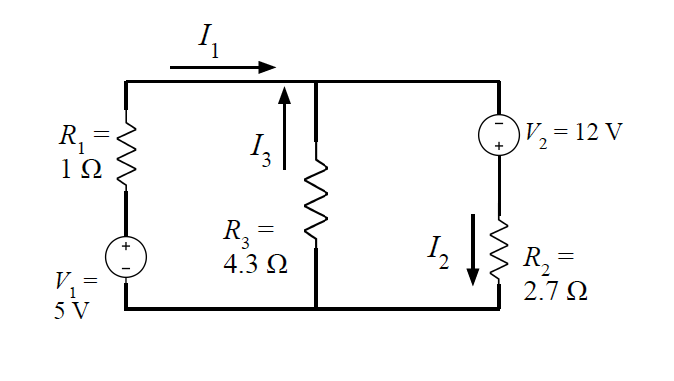

**Wrtie out the system of equations below:**

       $\Delta V_{\textrm{R1}} +\Delta V_{\textrm{R2}} -V_1 -V_2 =0$ → $I_1 R_1 +I_2 R_2 =17$

       $\Delta V_{\textrm{R3}} +\Delta V_{\textrm{R2}} -V_2 =I_3 R_3 +I_2 R_2 -12=0$ → $I_3 R_3 +I_2 R_2 =12$

       
$$I_1 -I_2 +I_3 =0$$
 

Here, we pre-define some known variables to make the next step easier:

% Define known variables
R1 = 1;
R2 = 2.7;
R3 = 4.3;
V1 = 5;
V2 = 12;

**Convert the system of equations into the form **$A\;x=b$**:**

% Define A and b below
A = [R1 R2 0; 0 R2 R3; 1 -1 1];
b = [17; 12; 0];

**Solve the matrix using backslash operator:**

% Type in the solution below 
A\b

ans =     4.6534
    4.5728
   -0.0806
